# This script file creates a plot for the part-02 of the experiment - 01

% Date: August 05, 2019
% Dr. Vibhav Durgesh
% Rev - 0.0
% Rev - 1.0 Modify for FA-2020
%%----END-----------------------------
clear all
close all
clc

## Experimental data for curve fitting

x = [0.00 1.00 2.00 3.00 4.00 5.00 6.00];
y = [0.7036 1.0096 1.3907 1.8867 2.2557 2.6313 2.9504];

## Performing linear curve fitting

[p,s] = polyfit(x,y,1); % Curve fiting data with 1st order fit

## Generate data for plotting curve fit

xfit = x; % Generating x-data for curve fitting
yfit = polyval(p,xfit); % Using polyval function to generate curve fit

## Reading all the relevant curvefit parameters

nu = s.df; % Getting degree of freedom for the curve fit
norm = s.normr; % Getting the norm of the curve fitting
syx = norm/sqrt(nu); % Calculating standard error of fit
slp = p(1); % Slope from curve fit
incpt = p(2); % Intercept from curve fit

## Generating figure with specific size

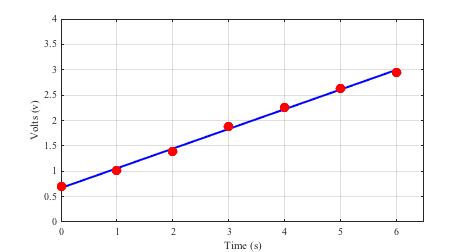

figure (1)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');
% Plotting data
plot(xfit,yfit,'b-','linewidth',2); hold on
plot(x,y,'ro','markersize',9,'markerfacecolor','r');
xlabel('Time (s)')
ylabel('Volts (v)')
ylim([0 4])
xlim([0 6.5])
grid on

## Adding 95% confidence level in the plot

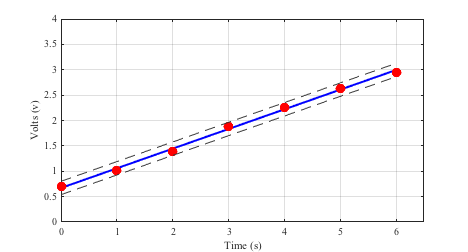

t_nuP = 2.571; % Value read from t-student's table
y_cl_low = yfit - t_nuP*syx; % Using regression analysis negative bound on curve fit
y_cl_up = yfit + t_nuP*syx; % Positive bound on curve fit

plot(xfit ,y_cl_low, '--', 'color', [0.2 0.2 0.2], 'HandleVisibility','off');
plot(xfit,y_cl_up,'--','color',[0.2 0.2 0.2]);

## Writing the curve fit equation on the graph

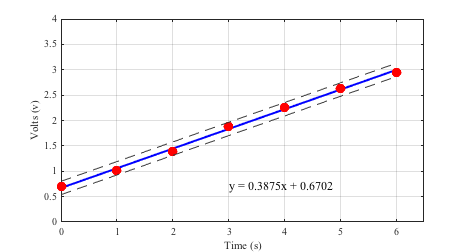

curvefitEq = sprintf('y = %2.4fx + %2.4f',slp,incpt);% Using sprintf to create string for equation
text(3,0.7,curvefitEq,'fontsize',12,'fontname','times'); % Writing curve fit equation at known location

## Adding legend to the curvefit data

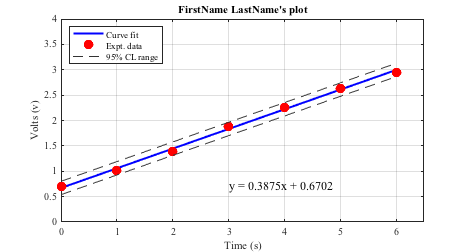

legend('Curve fit','Expt. data','95% CL range','location','Northwest')
title('FirstName LastName''s plot')

## Saving the files in png and pdf format

figName = ('../Figures/FirstName_LastName_ExptNo01_PartB');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf, 'Position');
set(gcf, 'PaperSize', figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')